# **NeuMa PreProcessed Dataset Handling**

## **Handling Pre-Processed Data**

Here, we aim to demonstrate the data loading and handling. Towards this end we introduce 4 different tasks that will be completed in this live scipt.

- Identify a particular product (given the page and product ID) and obtain all the relevant info

- Filter EEG data in $\alpha$-waves and obtain the EEG of all the products that were bought

- Identify all the products belonging to the "Milk" category.

Therefore the following of the script is organised based on the aforementioned tasks.

### Data Loading and Description

Initially we load the data for a particular participant (S01).

% Add all dependencies (Functions) to the Matlab Path
addpath(genpath('Dependencies\')); 
% Add Example Data (Subject 01, chanlocs, Prodct Descriptions) to the Matlab Path
addpath(genpath('PreProcessedData_Sample\'));
load S01.mat

Here we describe each and every variable that is being loaded:

#### *S01.Demographics.*

Contains the demographics for the particular participant. The following fields can be found:

- **Age:** A Numeric Value describing the participant's age

- **Gender:** Indicating the participant's gender. Its value is one of *{'male', 'female', 'other'}.*

- **DominantHand:** Indicating the participant's dominant hand. Its value is one of *{'right', 'left', 'ambidextrous'}*

- **Education: **Indicating the participant's education level. Its value is one of *{'basic', 'college', 'master', 'phd'}*

- **MaritalStatus:** Indicating the participant's marital status. Its value is one of *{'single', 'married', 'divorced'}*

- **Children:** Indicating if the participant is a parent. Its value is one of *{'yes', 'no'}*

#### *S01.Profile.*

Contains information with respect to the consumer's/participant's behaviour. Moreover, as obtained from the questionnaires, several attributes of the participant are described.

- **WeeklySupermarketVisits**: Describing how many times per week the participant visits a grocery store. Its value is one of *{'1-2 times', '2-3 times' , '>4 times'}.*

- **SupermarketVisitDuration**: Describing how long each visit in a grocery store lasts. Its value is one of *{'<15 minutes', '15-30 minutes', '30-60 minutes', '>60 minutes'}.*

- **PriceImpact**: How much is the participant affected (e.g. affects the participant's decision on whether to buy a product or not) by a product's price. Its value is in range of *1-10.*

- **BrandImpact**: How much is the participant affected (e.g. affects the participant's decision on whether to buy a product or not) by a product's brand. Its value is in range of *1-10.*

- **DiscountImpact**: How much is the participant affected (e.g. affects the participant's decision on whether to buy a product or not) when a product is on discount. Its value is in range of *1-10.*

- **AdvertisementImpact:** How much is the participant affected by advertisements on whether to buy a product or not. Its value is in range of *1-10.*

- **SuggestionImpact**: How much is the participant affected (e.g. affects the participant's decision on whether to buy a product or not) when a particular product was suggested by a friend, family member, etc. Its value is in range of *1-10.*

- **ShoppingList**: If the participant typically goes to a grocery shop having a list with the products that should be bought. Its value is one of *{'yes', 'no'}*.

- **VerbalVisual**: Describing where the participant lies in verbal-visual spectrum. Its value is in range of *1 (strongly verbal)* *up to 4 (strongly visual).*

- **Spontaneous**:Describing how much of a spontaneous consumer the participant is. Its value is in range of *1- 5.*

- **VarietySeeker**:Describing how much of a variety seeker consumer the participant is. Its value is in range of *1- 5.*

- **UtilitarianMotivation**: Describing how much the participant's decisions are driven by utilitarian motivations. Its value is in range of *1- 5.*

- **HedonicMotivation**: Describing how much the participant's decisions are driven by hedonic motivations. Its value is in range of *1- 5.*

- **Extraversion**: Quantifies extraversion (one of the big five personality traits) of the participant. Its value is in range of *1- 5.*

- **Agreeableness**: Quantifies agreeableness (one of the big five personality traits) of the participant. Its value is in range of *1- 5.*

- **Neuroticism**: Quantifies neuroticism (one of the big five personality traits) of the participant. Its value is in range of *1- 5.*

- **Openness**: Quantifies openness (one of the big five personality traits) of the participant. Its value is in range of *1- 5.*

- **Concentiousness**: Quantifies concentiousness (one of the big five personality traits) of the participant. Its value is in range of *1- 5.*

- **BargainHunter**: Quantifies how much of a bargain hunter (e.g., seeks bargains while buying) the participant is. Its value is in range of *1- 5.*

#### *S01.EEG_clean*

Contains the Data (recording and Fs) related to the EEG recording. The whole EEG recording (cleaned but NOT segmented) is provided here.

- **Data:** Multivariate EEG signals corresponding to the whole recording session (cleaned from artifacts). The signals are in the form of *[Num of Sensors x Num of Time Samples]*

- **Fs**: Sampling rate of EEG recording.

- **chans:** EEG sensor locations in the form of the typical chanlocs format.

#### *S01.ET_clean. *

Contains the Data (recording and Fs) related to the Eye Tracking recording. The whole Eye Tracking recording is provided here.

- **Data**: Eye tracking Signals in form [6 x Num of Time Samples]. The six rows correspond to: X coordinate of the left eye, Y coordinate of the left eye, pupil size of the left eye, X coordinate of the right eye, Y coordinate of the right eye, pupil size of the right eye. The coordinates are scaled in the range of [0-1]. Therefore to match the screen coordinates X should be scaled by 1920 and Y should be scaled by 1080.

- **Fs**: Sampling rate of eye Tracking recording.

#### *S01.PageX.ProductY.*

Contains information related to the Yth product (range 1-24) of Page X (range 1-6). There are in total six pages, each contaning/depicting 24 products.

- **EEG_segments: **Contains the EEG segments in the form of *[Num of segments x (starting sample, ending sample)]* that correspond to the recording while the participant was looking at this particular product.

- **ET_segments: **Contains the ET segments in the form of *[Num of segments x (starting sample, ending sample)]* that correspond to the recording while the participant was looking at this particular product.

- **ProductInfo.Bought:** The value is 1 if the participant bought the product during the experiment. Default value is 0 (the participant did not buy the product).

- **ProductInfo.Reasons:**If the ProductInfo.Bought is equal to 1, this describes the reasons for which the participant bought this product. The size of this variable may vary (depending on the number of reasons). Values are combinations, in the form of a cell array, of the following *{'price', 'brand', 'discount', 'type', 'need', 'like', 'regular', 'combination', 'alternative', 'other'}. *If ProductInfo.Bought is equal to 0 this is left empty.

- **ProductInfo.Familiarity: **If the ProductInfo.Bought is equal to 1, this field takes a value in the range of 1-5 and indicates how familiar is the participant with this product. The default value is 0 (If ProductInfo.Bought is also equal to 0; e.g., the product was NOT bought)

- **ProductInfo.FrequentBuy: **If the ProductInfo.Bought is equal to 1, this field takes a value in the range of 1-5 and indicates how frequently the participant buys this product. The default value is 0 (If ProductInfo.Bought is also equal to 0; e.g., the product was NOT bought).

- **ProductInfo.Description: **Describing the general product caterogy that each product belongs to (e.g., milk, cheese, cerials, etc).

Having all the variables/fields described, we now proceed to demonstration of Task 1: Identify a particular product (given the page and product ID) and obtain all the relevant info.

### Task 1: Product Identification and Information extraction

Let's say we are willing to retrieve all the information that is related to Product No 21 of the 3rd Page.

In order to get an informed idea about the aforementioned product (i.e., Product No 21 of the 3rd Page), we have to load the corresponding Page image and plot the associated bounding box.

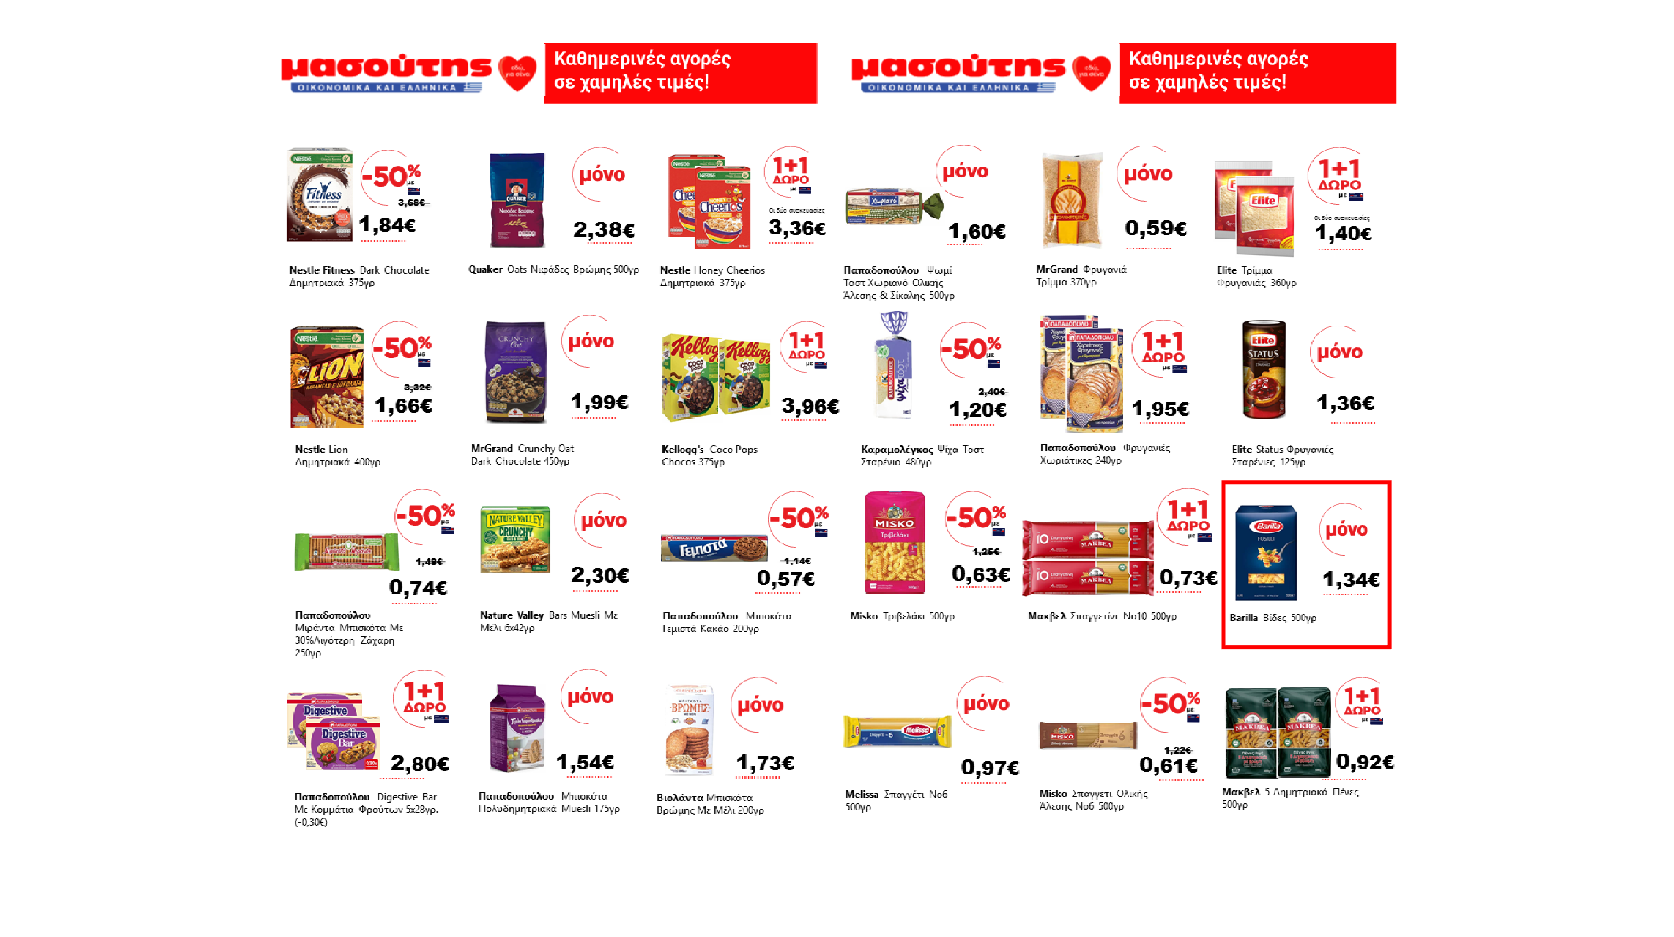

%% Constants
PAGE_ID = 3;
PRODUCT_ID = 21;

% load the page image
pageImage = imread(['ImagePage_' num2str(PAGE_ID) '.tif']); 
% load the bounding boxes corresponding to that page.
% This adds to the workspace a cell array named ROI_list
load(['BoundingBoxPage_' num2str(PAGE_ID) '.mat']); 

imshow(pageImage), hold on % show the page
productBox = ROI_list{PRODUCT_ID}; % (x, y, width, height)
% plot the bounding box of this particular product ID
rectangle('Position', productBox, 'EdgeColor', 'r', 'LineWidth', 3), hold off 

The segments calculated for these products are based on the depicted Bounding Box. The segments correspond to when the participants gaze was falling within this bounding box. There are several segments since the participant may have wondered around the products and looked at this one several times during the experiment.

Then we will isolate the EEG and ET segments that correspond to this particular products. This part shows how one may obtain the actual EEG signals for each product from the corresponding *S01.SlideX.ProductY.EEG_segments*

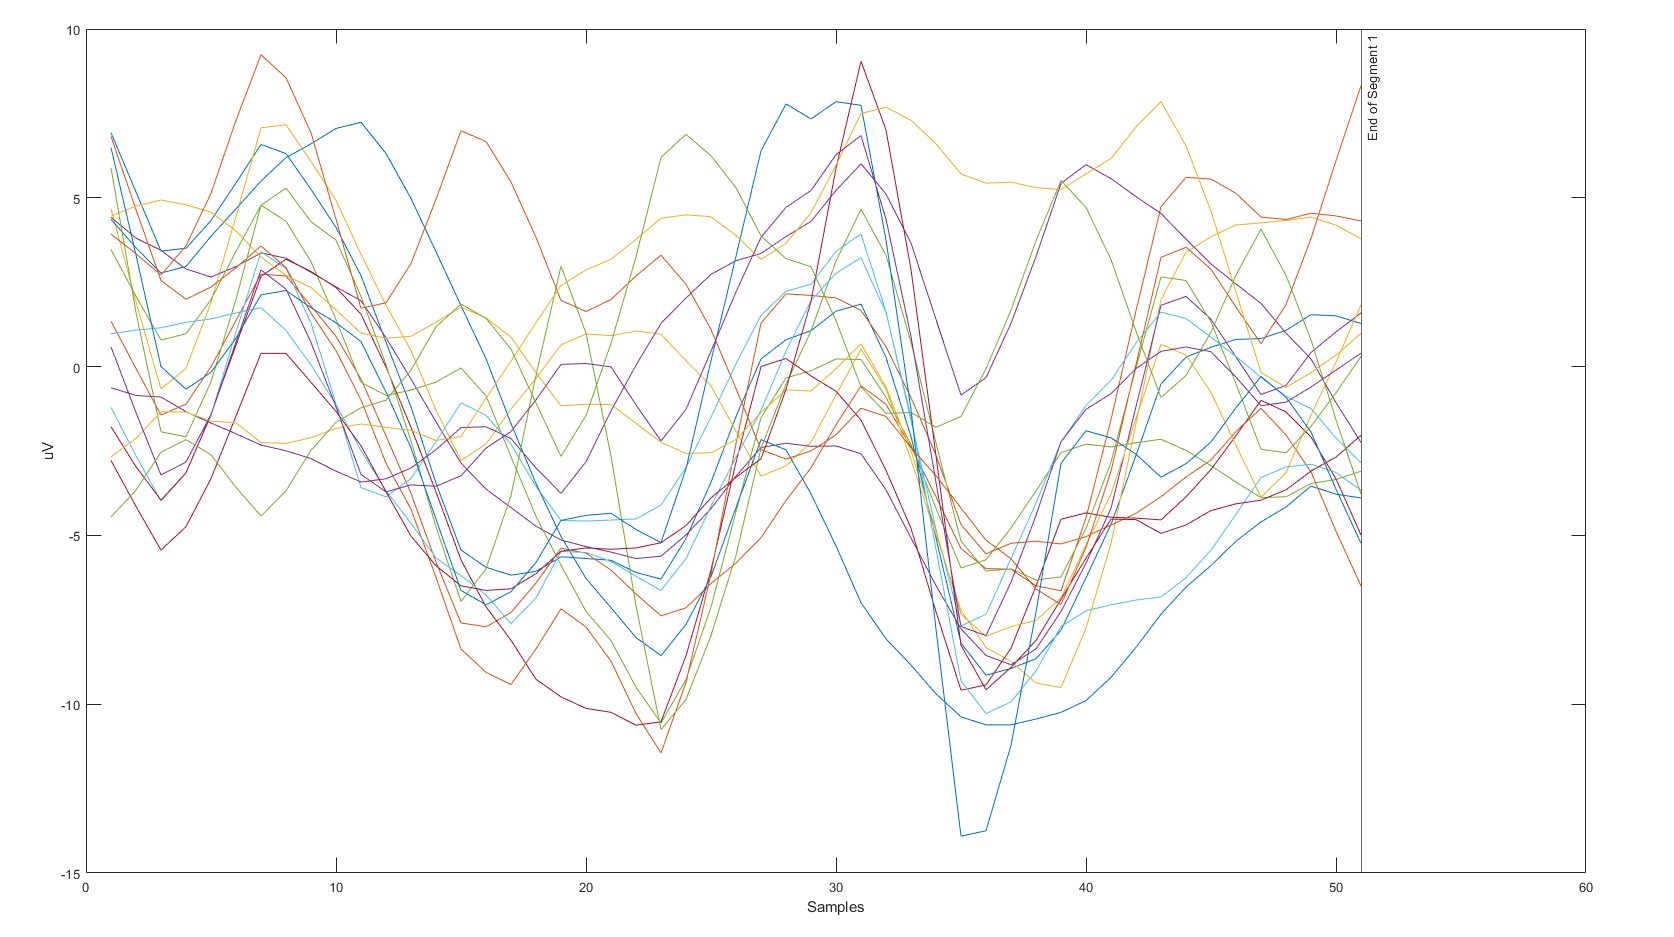

productEEG = {}; % Initialize a cell array for EEG
myProduct = S01.(strcat('Page', int2str(PAGE_ID))).(strcat('Product', int2str(PRODUCT_ID)));

for iSegment = 1 : size(myProduct.EEG_segments, 1)
    startSample = myProduct.EEG_segments(iSegment, 1);
    endSample = myProduct.EEG_segments(iSegment, 2);
    % Get the actual EEG signal
    productEEG{iSegment} = S01.EEG_clean.Data(:, startSample : endSample); 
end

%% Plot segments
concatenatedEEG = [];
segmentBreak = [];
for iSegment = 1 : size(myProduct.EEG_segments, 1)
    % Concantenate EEG signals in a single variable
    concatenatedEEG = [concatenatedEEG productEEG{iSegment}];
    % Tracks where segments change so we can plot xlines
    segmentBreak(end+1) = size(concatenatedEEG, 2); 
end

plot (concatenatedEEG'), hold on, xlabel('Samples'), ylabel('uV')
for i_break = 1 : length(segmentBreak)
    xline(segmentBreak(i_break), '-', {['End of Segment ' num2str(i_break)]});
end, hold off

As it can be seen some segments are realy small (e.g., only a few samples long). These segments should probably be discarded in analysis since they correspond to responses when the eyes were moving from one product to another and coincidentally passed over this particular product.

In a similar approach we can obtain the corresponding Eye Tracking signals. Here we will plot the pupil dilations that correspond to when viewing this product.

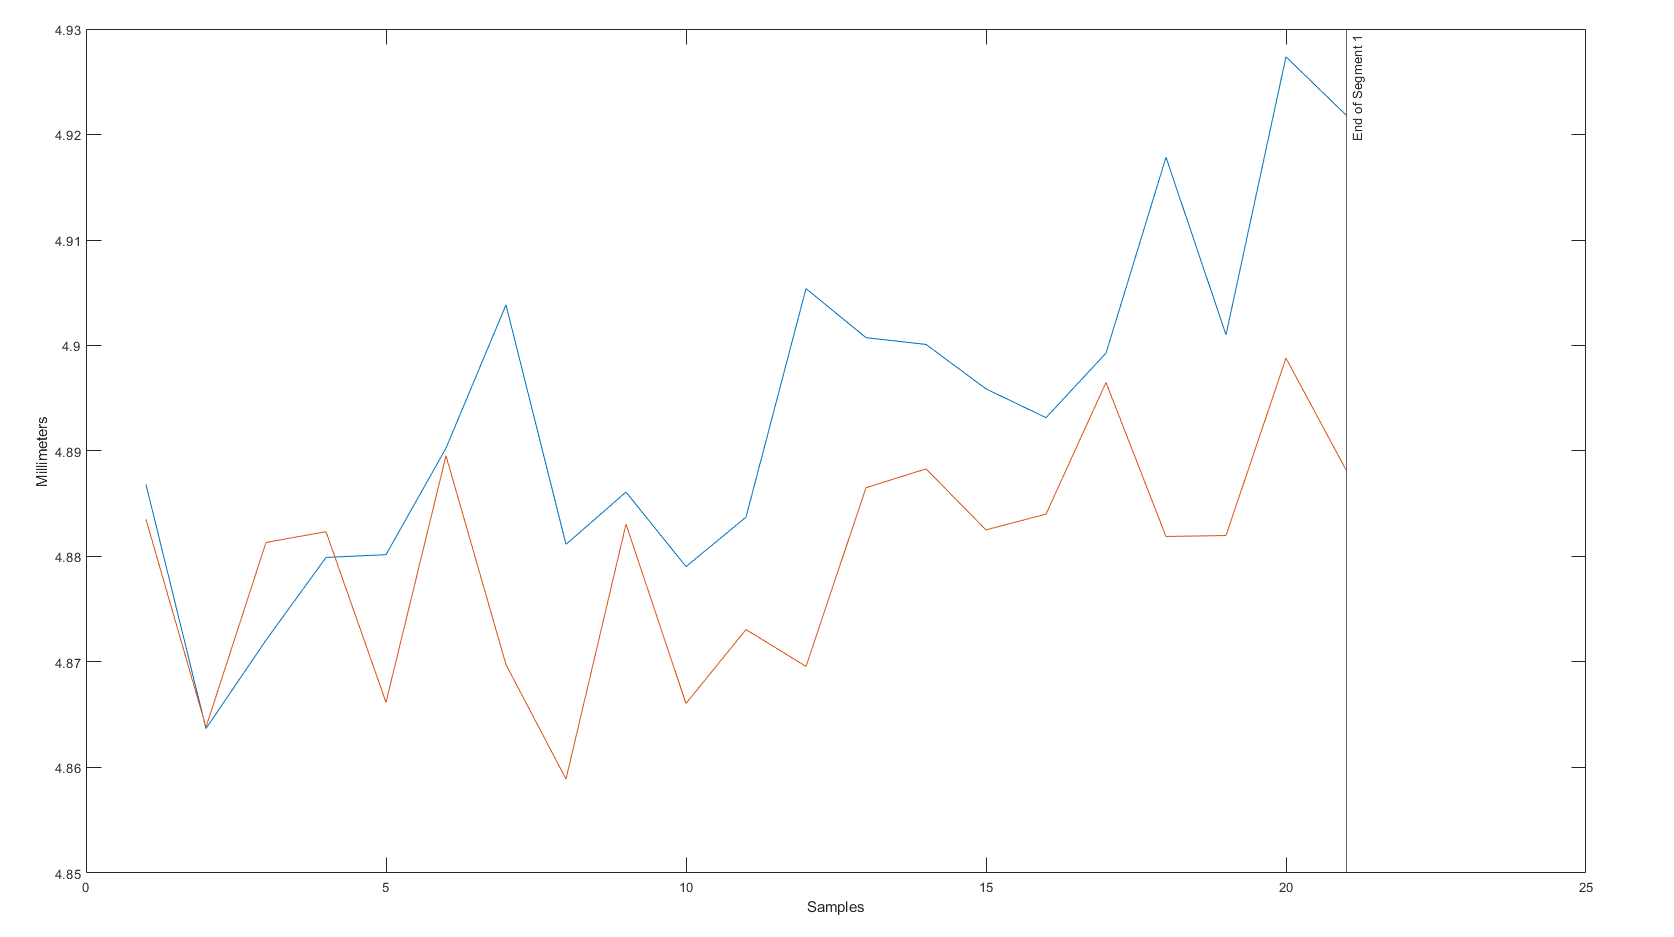

productET = {}; % Initialize a cell array for ET
myProduct = S01.(strcat('Page', int2str(PAGE_ID))).(strcat('Product', int2str(PRODUCT_ID)));

for iSegment = 1 : size(myProduct.ET_segments, 1)
    startSample = myProduct.ET_segments(iSegment, 1);
    endSample = myProduct.ET_segments(iSegment, 2);
    % 3rd and 6th rows corresponds to pupil dilation of the left and right eye
    productET{iSegment} = S01.ET_clean.Data([3 6], startSample : endSample);
end

%% Plot segments
concatenatedET = [];
segmentBreak = [];
for iSegment = 1 : size(myProduct.ET_segments, 1)
    % Concantenate dilation signals in a single variable
    concatenatedET = [concatenatedET productET{iSegment}];
    % Tracks where segments change, so we can plot xlines
    segmentBreak(end+1) = size(concatenatedET, 2); 
end

plot (concatenatedET'), hold on, xlabel('Samples'), ylabel('Millimeters')
for i_break = 1 : length(segmentBreak)
    xline(segmentBreak(i_break), '-', {['End of Segment ' num2str(i_break)]});
end, hold off

### Task 2: Alpha Activity of EEG for the prodcuts that were Bought

Here we aim to isolate the alpha brainwaves corresponding to the products that were bought from the participant.

In order to avoid distortions we will initially filter the whole EEG signal (e.g., EEG_clean.Data) and then keep the corresponding segments.

EEGFs = S01.EEG_clean.Fs;
[b, a] = butter(3, [8 12]/(EEGFs/2));
filteredEEG = filtfilt(b, a, S01.EEG_clean.Data')';

After having the EEG signal filtered, we iterate over all the products and check the field .ProductInfo.Bought which indicates whether it was bought (value equal to 1) by the participant or not (value equal to 0).

indicesBought = [];
for iPage = 1 : 6 % iterate over pages
    for iProduct = 1 : 24 % iterate over products
        pageNo = int2str(iPage);
        productNo = int2str(iProduct);
        if S01.(strcat('Page',pageNo)).(strcat('Product',productNo)).ProductInfo.Bought == 1
            % Store Page_ID and Product_ID of the products that were bought
            indicesBought(end+1,:) = [iPage, iProduct]; 
        end
    end
end

Having the indices of the products that were bought indentified we may isolate the corresponding filtered EEG segments as in **Task 1: Product Identification and Information extraction**. Here we demonstrate it only on the first product that was bought. We note that we do not plot the segments of EEG whose duration is smaller than half a second.

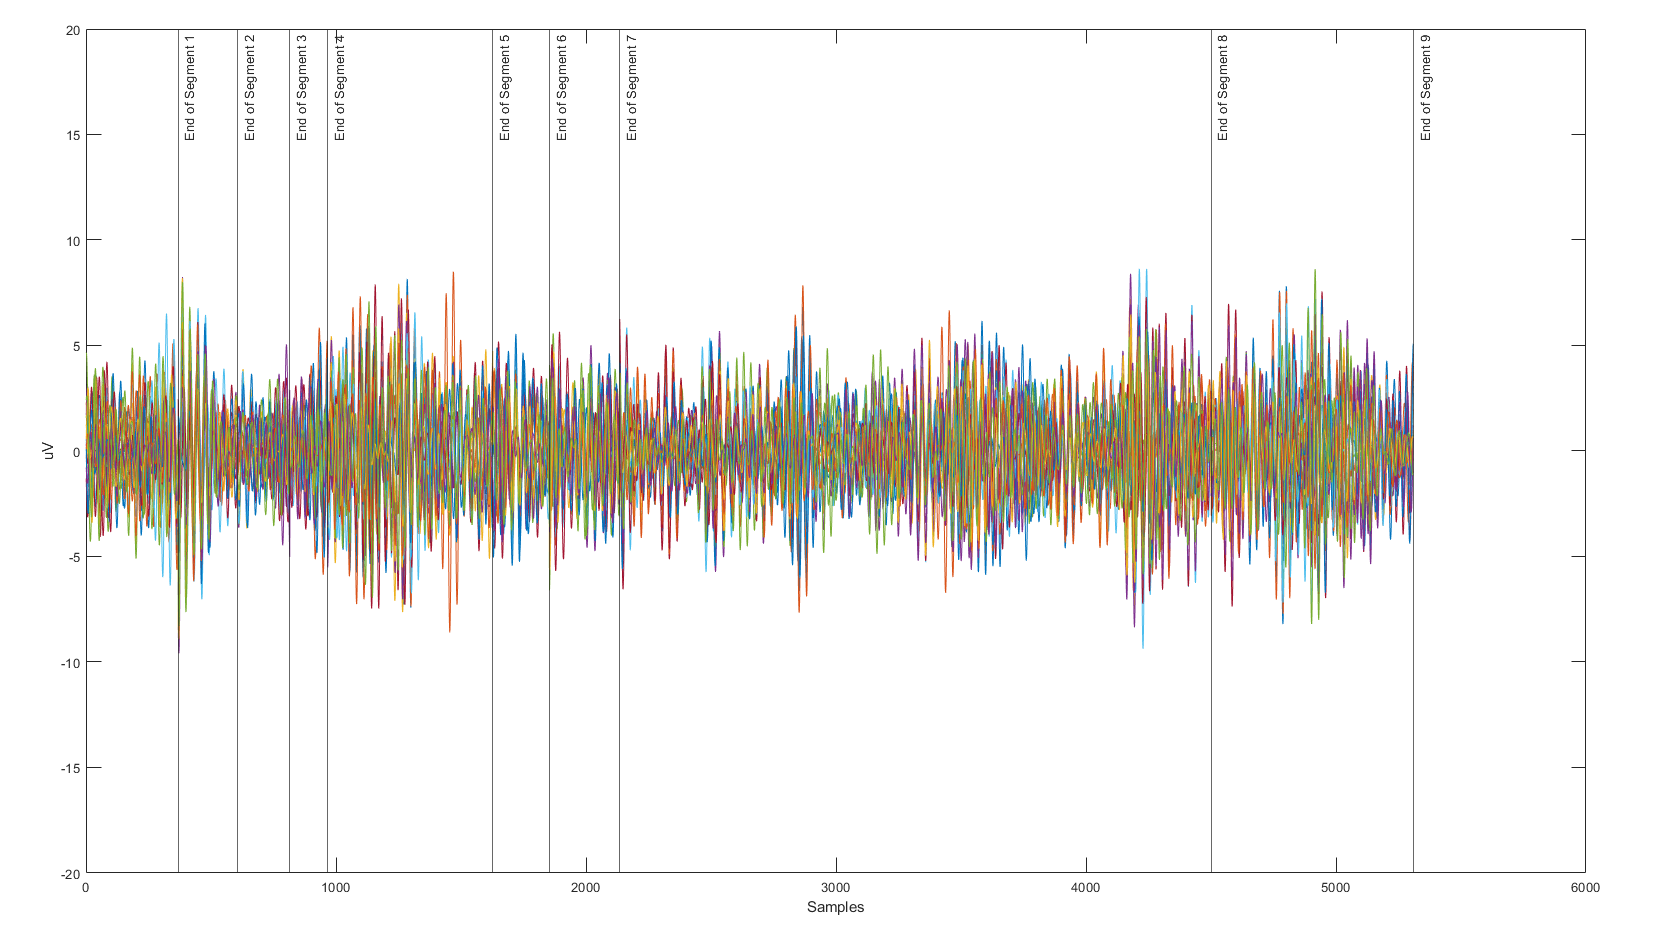

productEEG = {}; % Initialize a cell array for EEG
myProduct = ...
S01.(strcat('Page', int2str(indicesBought(1,1))))...
.(strcat('Product', int2str(indicesBought(1,2))));

for iSegment = 1 : size(myProduct.EEG_segments, 1)
    startSample = myProduct.EEG_segments(iSegment, 1);
    endSample = myProduct.EEG_segments(iSegment, 2);
    % Get the actual EEG signal
    productEEG{iSegment} = filteredEEG(:, startSample : endSample); 
end

%% Plot segments
concatenatedEEG = [];
segmentBreak = [];
for iSegment = 1 : size(myProduct.EEG_segments, 1)
    % Do not plot segments with duration smaller than half a second
    if size(productEEG{iSegment},2)<EEGFs/2 
        continue
    end
    % Concantenate EEG signals in a single variable
    concatenatedEEG = [concatenatedEEG productEEG{iSegment}]; 
    % Tracks where segments change so we can plot xlines
    segmentBreak(end+1) = size(concatenatedEEG, 2); 
end

plot (concatenatedEEG'), hold on, xlabel('Samples'), ylabel('uV'), ylim([-20 20])
for i_break = 1 : length(segmentBreak)
    xline(segmentBreak(i_break), '-', {['End of Segment ' num2str(i_break)]});
end, hold off

#### Task 3: Identify all the products of a particular category

Here we aim to identify all the products of a particular description (e.g. all the milks). Therefore, we have to iterate over all the available products (for each of the six pages).

In the following code, we iterate over all products in order to create a list that contains all the unique available product descriptions

allDescriptions = {};
for iPage = 1 : 6 % iterate over pages
    for iProduct = 1 : 24 % iterate
        pageNo = int2str(iPage);
        productNo = int2str(iProduct);
        allDescriptions{end+1} = ...
        S01.(strcat('Page',pageNo)).(strcat('Product',productNo)).ProductInfo.Description;
    end
end
uniqueDescriptions = unique(allDescriptions)

uniqueDescriptions = 1×66 cell array
    {'Beer'}    {'Biscuits'}    {'Bread'}    {'Breadcrumbs'}    {'Cereal Bar'}    {'Cereals'}    {'Cheese'}    {'Cheese Pie'}    {'Chicken Nuggets'}    {'Chips'}    {'Chips Peanut'}    {'Chloride'}    {'Cider'}    {'Cleanser'}    {'Coke'}    {'Detergent'}    {'Dish Washing liquid'}    {'Espresso'}    {'Fat Cleanser'}    {'Filtered Coffee'}    {'Gin'}    {'Greek Coffee'}    {'Ham'}    {'Honey'}    {'Ice Cream'}    {'Lemonade'}    {'Liquid Soap'}    {'Marmelade'}    {'Meatballs'}    {'Milk'}    {'Mixed Vegetables'}    {'Mustard'}    {'Napkins'}    {'Oats'}    {'Orange Juice'}    {'Pacotinia'}    {'Pasta'}    {'Peas'}    {'Pizza'}    {'Pods'}    {'Pop Corn'}    {'Potato Pie'}    {'Red Beer'}    {'Red Wine'}    {'Rose Wine'}    {'Rum'}    {'Salami'}    {'Sausage Pie'}    {'Sliced Cheese'}    {'Smoothie'}    {'Soap'}    {'Soft Cheese'}    {'Softener'}    {'Spagheti'}    {'Spinach'}    {'Spinach Pie'}    {'Tahini'}    {'Toasts'}    {'Toilet Paper'}    {'T

In the following code segment we identify all the products that are being described as "Milk"

milkIDs = [];
for iPage = 1 : 6 % iterate over pages
    for iProduct = 1 : 24 % iterate
        pageNo = int2str(iPage);
        productNo = int2str(iProduct);
        if strcmp(S01.(strcat('Page',pageNo))...
           .(strcat('Product',productNo)).ProductInfo.Description, 'Milk')
            % Store Page_ID and Product_ID of the products that were bought
            milkIDs(end+1,:) = [iPage, iProduct]; 
        end
    end
end
milkIDs'

ans =      1     1     1     1     1     1
    13    14    15    16    17    18


With all the "Milk" products being identified (each couple indicates the corresponding Page and product ID of this page), one can follow the example of **Task 1** in order to isolate the corresponding EEG and Eye-Tracking segments.